Demodulation(four_QAM([1 0], 1))

ans =      1     0


Convolution_code([1 1])

ans =      1     1     0     1     0     1     1     1


binVal = de2bi(0:3, 2, 'left-msb')  % path metric 계산을 위한 계산

binVal =      0     0
     0     1
     1     0
     1     1


for i = 1:4
    output0(i,:) = Convolution_code_tail_bit_X(0, binVal(i,1:2))
    output1(i,:) = Convolution_code_tail_bit_X(1, binVal(i,1:2))
end

output0 =      0     0
     1     1
     1     0
     0     1


output1 =      1     1
     0     0
     0     1
     1     0


output0 =      0     0
     1     1
     1     0
     0     1


output1 =      1     1
     0     0
     0     1
     1     0


output0 =      0     0
     1     1
     1     0
     0     1


output1 =      1     1
     0     0
     0     1
     1     0


output0 =      0     0
     1     1
     1     0
     0     1


output1 =      1     1
     0     0
     0     1
     1     0


clc
clear
close
input = randsrc(1, 200, [0 1])

input =      1     0     1     0     0     1     0     1     0     0     1     1     1     1     0     1     0     0     1     0     1     0     0     1     0     0     1     1     0     1     0     0     1     1     1     0     1     0     0     0     0     0     0     1     0     0     1     1     1     0


encoded_input = Convolution_code(input)

encoded_input =      1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     1     0


for i = 1:length(encoded_input)/2
    modulated_output(1,2*(i-1)+1 : 2*i)=four_QAM(encoded_input(1,2*(i-1)+1 : 2*i), 40);
end
received_signal = AWGN_Channel(modulated_output,2);
for i = 1:length(modulated_output)/2
    demodulated_output(1,2*(i-1)+1 : 2*i)=Demodulation(received_signal(1,2*(i-1)+1 : 2*i))
end

demodulated_output =      1     1


demodulated_output =      1     1     1     0


demodulated_output =      1     1     1     0     0     0


demodulated_output =      1     1     1     0     0     0     1     0


demodulated_output =      1     1     1     0     0     0     1     0     1     1


demodulated_output =      1     1     1     0     0     0     1     0     1     1     1     1


demodulated_output =      1     1     1     0     0     0     1     0     1     1     1     1     1     0


demodulated_output =      1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0


demodulated_output =      1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0


demodulated_output =      1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1


demodulated_output =      1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1


demodulated_output =      1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1


demodulated_output =      1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0


demodulated_output =      1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0


demodulated_output =      1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output =      1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1     0     0


demodulated_output =      1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1     0     0     1     0


demodulated_output =      1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1     0     0     1     0     1     1


demodulated_output =      1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1     0     0     1     0     1     1     1     1


demodulated_output =      1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1     0     0     1     0     1     1     1     1     1     0


demodulated_output =      1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1     0     0     1     0     1     1     1     1     1     0     0     0


demodulated_output =      1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1     0     0     1     0     1     1     1     1     1     0     0     0     1     0


demodulated_output =      1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1


demodulated_output =      1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1


demodulated_output =      1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     1     0


demodulated_output =      1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     1     0


demodulated_output =      1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     1     0


demodulated_output =      1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     1     0


demodulated_output =      1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     1     0


demodulated_output =      1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     1     0


demodulated_output =      1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     1     0


demodulated_output =      1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     1     0


demodulated_output =      1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     1     0


demodulated_output =      1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     1     0


demodulated_output =      1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     1     0


demodulated_output =      1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     1     0


demodulated_output =      1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     1     0


demodulated_output =      1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     1     0


demodulated_output =      1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     1     0


demodulated_output =      1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     1     0


demodulated_output =      1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     1     0


demodulated_output =      1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     1     0


demodulated_output =      1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     1     0


demodulated_output =      1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     1     0


demodulated_output =      1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     1     0


demodulated_output =      1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     1     0


demodulated_output =      1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     1     0


demodulated_output =      1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     1     0


demodulated_output = 1×98
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×100
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×102
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×104
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×106
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×108
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×110
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×112
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×114
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×116
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×118
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×120
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×122
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×124
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×126
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×128
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×130
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×132
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×134
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×136
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×138
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×140
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×142
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×144
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×146
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×148
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×150
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×152
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×154
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×156
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×158
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×160
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×162
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×164
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×166
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×168
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×170
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×172
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×174
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×176
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×178
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×180
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×182
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×184
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×186
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×188
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×190
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×192
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×194
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×196
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×198
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×200
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×202
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×204
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×206
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×208
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×210
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×212
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×214
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×216
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×218
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×220
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×222
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×224
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×226
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×228
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×230
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×232
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×234
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×236
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×238
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×240
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×242
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×244
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×246
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×248
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×250
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×252
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×254
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×256
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×258
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×260
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×262
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×264
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×266
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×268
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×270
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×272
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×274
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×276
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×278
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×280
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×282
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×284
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×286
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×288
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×290
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×292
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×294
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×296
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×298
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×300
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×302
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×304
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×306
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×308
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×310
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×312
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×314
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×316
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×318
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×320
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×322
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×324
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×326
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×328
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×330
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×332
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×334
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×336
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×338
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×340
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×342
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×344
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×346
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×348
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×350
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×352
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×354
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×356
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×358
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×360
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×362
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×364
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×366
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×368
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×370
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×372
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×374
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×376
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×378
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×380
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×382
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×384
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×386
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×388
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×390
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×392
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×394
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×396
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×398
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×400
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×402
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


demodulated_output = 1×404
     1     1     1     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     0     0     1


decoding = Viterbi_decoding(demodulated_output, 200)

decoding = 1×200
     1     0     1     0     0     1     0     1     0     0     1     1     1     1     0     1     0     0     1     0     1     0     0     1     0     0     1     1     0     1


a = nnz(input-decoding)

a = 2

% soft decision
clc
clear
close
%input = randsrc(1, 10, [0 1])
input = [1 0];
encoded_input = Convolution_code(input)

encoded_input =      1     1     1     0     1     1     0     0


for i = 1:length(encoded_input)/2
    modulated_output(1,i)=four_QAM(encoded_input(1,2*(i-1)+1 : 2*i), 20);
end
received_signal = AWGN_Channel(modulated_output,2)

received_signal =   -4.7016 - 5.3404i   3.9050 - 3.0972i  -3.6134 - 2.0572i   5.3970 + 5.3635i


received_signal=[real(received_signal);imag(received_signal)]

received_signal =    -4.7016    3.9050   -3.6134    5.3970
   -5.3404   -3.0972   -2.0572    5.3635


decoding = Viterbi_soft_decoding(received_signal, 2, 20)

decoding =      1     0


a = nnz(input-decoding)

a = 0

%awgn
clear
close
t = 0:pi/16:2*pi;
x = sqrt(2)*(sin(t)+ 1i *sin(t));
rng('default')
noise_v = 2

noise_v = 2

Esym=sum(abs(x).^2)/(length(x))

Esym = 1.9394

snr = Esym/(2*noise_v^2)

snr = 0.2424

rxSig = awgn(x,10*log10(snr), 'measured')

rxSig =    1.0753 - 1.6190i   3.9437 - 5.6127i  -3.9765 + 3.4180i   2.5100 + 1.4361i   1.6375 - 0.5099i  -1.4395 + 3.9165i   0.4394 - 2.1165i   2.0723 + 1.1826i   8.5710 + 0.9313i   6.9259 + 2.0255i  -1.3932 + 1.9323i   7.2457 - 0.5539i   2.4508 + 0.9399i   0.6596 + 0.4559i   1.9707 + 1.7966i  -0.1340 + 2.4624i  -0.2483 + 2.2185i   2.7035 - 2.0032i   2.2769 - 0.3865i   2.0487 - 3.2139i   0.3430 - 3.2270i  -3.5908 - 1.1896i   0.1279 + 1.7587i   1.8734 - 2.9264i  -0.4364 - 0.6715i   0.6823 - 1.8382i   0.1472 + 0.9281i  -1.7828 - 3.3540i  -0.4123 - 0.9349i  -2.3603 + 0.3194i   1.2356 + 1.6600i  -2.5700 + 2.8125i  -2.1377 + 0.1719i


rng('default')


rxSig3 = AWGN_Channel(x, noise_v)

rxSig3 =    1.0753 - 1.6190i   3.9437 - 5.6127i  -3.9765 + 3.4180i   2.5100 + 1.4361i   1.6375 - 0.5099i  -1.4395 + 3.9165i   0.4394 - 2.1165i   2.0723 + 1.1826i   8.5710 + 0.9313i   6.9259 + 2.0255i  -1.3932 + 1.9323i   7.2457 - 0.5539i   2.4508 + 0.9399i   0.6596 + 0.4559i   1.9707 + 1.7966i  -0.1340 + 2.4624i  -0.2483 + 2.2185i   2.7035 - 2.0032i   2.2769 - 0.3865i   2.0487 - 3.2139i   0.3430 - 3.2270i  -3.5908 - 1.1896i   0.1279 + 1.7587i   1.8734 - 2.9264i  -0.4364 - 0.6715i   0.6823 - 1.8382i   0.1472 + 0.9281i  -1.7828 - 3.3540i  -0.4123 - 0.9349i  -2.3603 + 0.3194i   1.2356 + 1.6600i  -2.5700 + 2.8125i  -2.1377 + 0.1719i


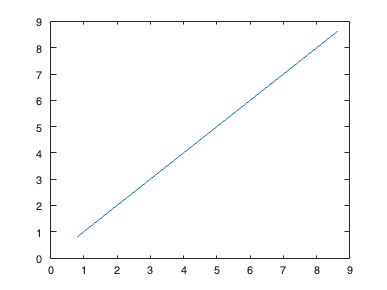

axis([0 9 0 9])
xticks(0:1:9)

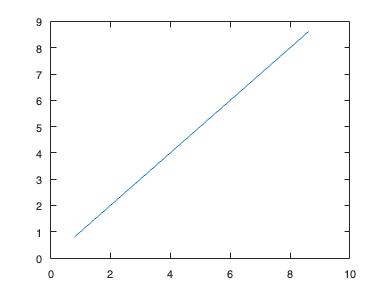

figure; plot(abs(rxSig),abs(rxSig3));

% 4qam test
clc
close
clear
ber = zeros(25,1);
Eb_No_db_sim = 1:25;
N_symbol = 300000

N_symbol = 300000

sigma_v = 4;
parfor i = Eb_No_db_sim
    for j = 1:N_symbol
        a = randi([0 1], [1 2]);
        b = four_QAM(a, 2*(10^(i/10))*2*sigma_v^2);
        c = AWGN_Channel(b, sigma_v);
        d = Demodulation(c);
        k = nnz(a-d);
        ber(i, 1) = ber(i, 1) + k;
    end
end
ber = ber / (N_symbol*2);

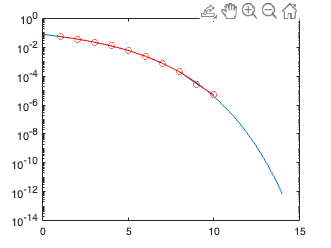


eb_no_db = 0:0.1:14;
semilogy(eb_no_db, qfunc(sqrt(2*10.^(eb_no_db/10))))
hold on
plot(Eb_No_db_sim, ber, 'ro-')